# Support vector machines

A support vector machine (SVM) is simply a kernelized version of a support vector classifier. We will again use the `fitcsvm` function to train the classifier, but now we will specify a kernel function.

Generate synthetic data for 2 classes in 2-D. The centers of the two classes are close enough so that there likely will not be a linear separator of the data for the two classes.

%rng(14);       % random number seed
n = 20; % number of data points in each of two classes
x = [randn(n,2)+1.0; randn(n,2)-1.0]; % data points
y = [ones(n,1); -ones(n,1)];          % class labels

Select the inverse regularization parameter and the kernel length scale. Then train the SVM.

C = 65; % inverse regularization parameter
ks = 1.3; % Gaussian kernel length scale
model = fitcsvm(x, y, 'KernelFunction','rbf', 'KernelScale', ks, "BoxConstraint", C);

Plotting the decision surface will be more complicated than in the linear case. We'll compute the values of the discriminant on a mesh, and then use the `contour` function to plot the decision surface.

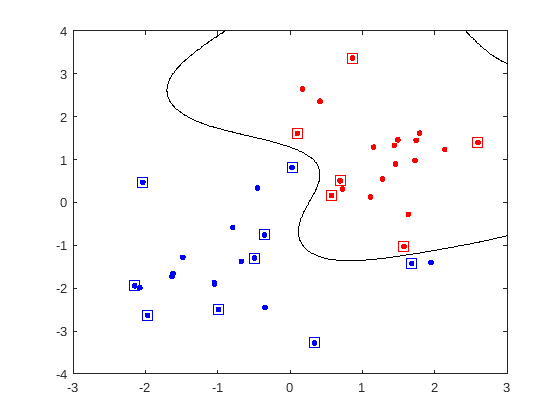

[xx, yy] = meshgrid(-4:.02:4, -4:.02:4);
[~, scores] = predict(model, [xx(:),yy(:)]);
% plot training data
gscatter(x(:,1),x(:,2),y,'br','.',10,'off');
hold on
% plot support vectors
gscatter(model.SupportVectors(:,1), model.SupportVectors(:,2), ...
    model.SupportVectorLabels, 'br', 's', 10, 'off')
% plot decision surface using a contour at level value 0
contour(xx,yy,reshape(scores(:,2),size(xx)),[0 0],'k');
hold off

### Taking it further

Do you expect the locations of the support vectors? For support vectors that you do not expect, what is their distance from the discriminant? 

Experiment with different values of the kernel length scale. Explain what you see. 